## ***EXERCISE:***

## *** TASK 1:***

-  1. Let input signal x be [2, 1, –2, 4, -1] and the system h be [-2, 3, 4, –3, 7]. Find the output of the system y by 

- using the conv command 

- 2. Now suppose we add another system j = [4, –1, 2, 3, 1] in series with the above system. Now find the overall response and output y of the above system using the conv command. 

- 3. Again suppose now j is attached in parallel to h and the result is series with x. Plot the resultant signal. 

- 4. Now suppose the two systems h and j are in series and a third system k = [6, 5, 4, 3, 2] has been attached with them in parallel and the result is series with x. Plot the overall signal y. 

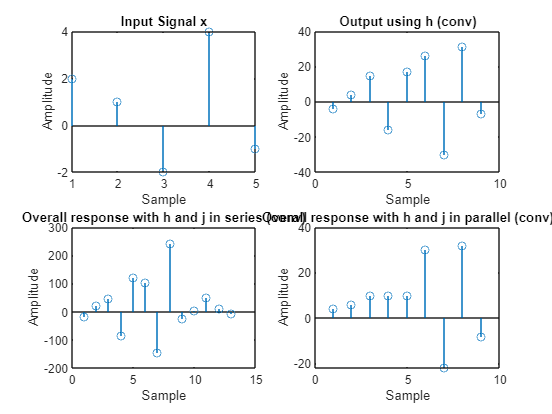


% Input signal
x = [2, 1, -2, 4, -1];

% System h
h = [-2, 3, 4, -3, 7];

% System j
j = [4, -1, 2, 3, 1];

% System k
k = [6, 5, 4, 3, 2];

% Convolution with h using conv command
y1 = conv(x, h);

% Overall response with h and j in series (conv)
hj = conv(h, j);
y2 = conv(x, hj);

% j in parallel with h, then series with x (conv)
hj_parallel = h + j;
y3 = conv(x, hj_parallel);

% h and j in series
hj_series = conv(h,j);

% Zero-pad the shorter vector (k) to match hj_series length
k_padded = [k, zeros(1, length(hj_series) - length(k))];

% Combine hj_series and k_padded (effectively parallel connection)
result = hj_series + k_padded;

% Series with x (conv)
y4 = conv(x, result);

% Plot results separately
figure;
subplot(221);
stem(x);
title('Input Signal x');
xlabel('Sample');
ylabel('Amplitude');

subplot(222);
stem(y1);
title('Output using h (conv)');
xlabel('Sample');
ylabel('Amplitude');

subplot(223);
stem(y2);
title('Overall response with h and j in series (conv)');
xlabel('Sample');
ylabel('Amplitude');

subplot(224);
stem(y3);
title('Overall response with h and j in parallel (conv)');
xlabel('Sample');
ylabel('Amplitude');

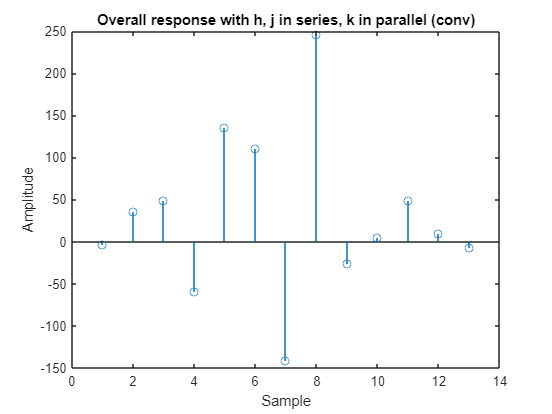


figure;
stem(y4);
title('Overall response with h, j in series, k in parallel (conv)');
xlabel('Sample');
ylabel('Amplitude');

## **TASK 2: **

Write a MATLAB code to: 

-  Generate a discrete time sinusoidal signal cos(2πf0n) with any frequency of your choice and using a predefined time axis. The time axis should be defined so that the signal exists for 10 time periods. 

-  Generate another discrete time sinusoidal signal sin(2πf0n) with the same frequency and time axis. 

-  Find the cross correlation of the two signals using the predefined MATLAB function. 

-  Plot all of the above as discrete time signals, with proper independent axis, and label all plots

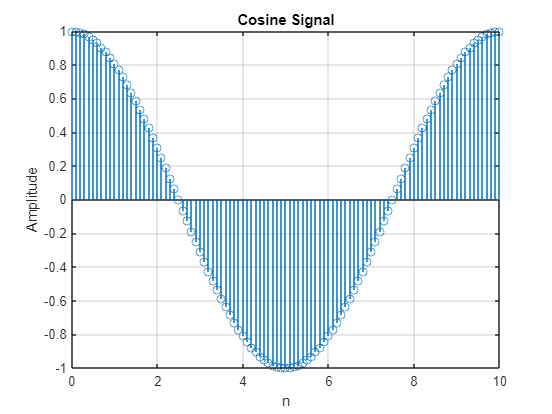

% Generate a discrete time sinusoidal signal cos(2πf0n) with any frequency
f0 =  0.1; % Frequency of the sinusoidal signal
n = 0:0.1:10; % Predefined time axis for 10 time periods
x1 = cos(2*pi*f0*n); % Generate the cosine signal
% Generate another discrete time sinusoidal signal sin(2πf0n) with the same frequency and time axis
x2 = sin(2*pi*f0*n); % Generate the sine signal

% Find the cross correlation of the two signals
cross_corr = xcorr(x1, x2);

% Plot all of the signals with proper labeling
figure;

% Plot the first sinusoidal signal

stem(n, x1);
xlabel('n');
ylabel('Amplitude');
title('Cosine Signal');
grid on;

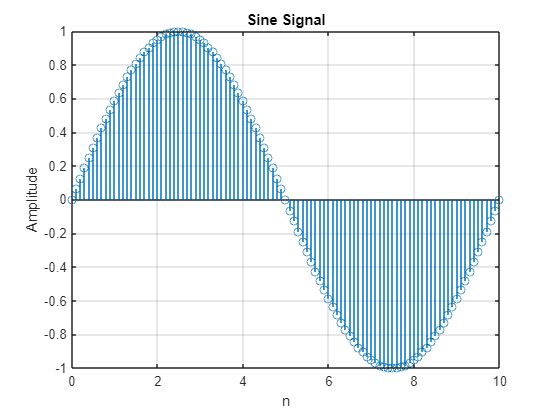


% Plot the second sinusoidal signal

stem(n, x2);
xlabel('n');
ylabel('Amplitude');
title('Sine Signal');
grid on;

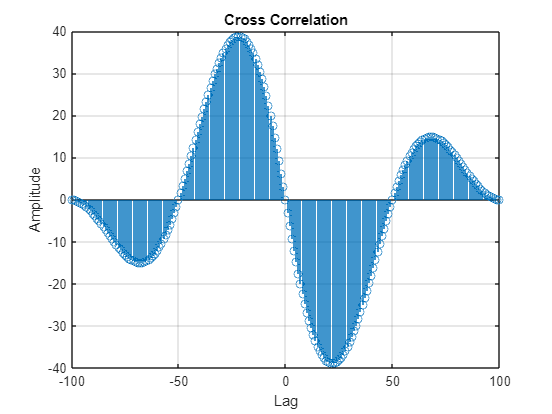


% Plot the cross correlation of the two signals
L = length(cross_corr);
lag = -(L-1)/2:(L-1)/2;

stem(lag, cross_corr);
xlabel('Lag');
ylabel('Amplitude');
title('Cross Correlation');
grid on;